# **Runge-Kutta Method Code**

## Input

% interval [a,b]
a=0;    % start point of the interval
b=30;    % end point of the interval
n=100;  % iteration number
h=(b-a)/n;    %step size

## **X discretization:**

x=a:h:b;    % x discretization 

## Initial Condition

%% intial condition
y=zeros(size(x));

## Differential Eq.   y'=f(x,y) = sin(x+y)

% The loop to solve the DE
% and find the 1st value of Y
for i=1:n
    k1 = sin(x(i)+y(i)); %first K
   
    k2 = sin((x(i)+h/2)+(y(i)+(h/2)*k1)); %2nd K
    
    k3 = sin((x(i)+h/2)+(y(i)+(h/2)*k2)); %3rd K
    
    k4 = sin((x(i)+h)+(y(i)+h*k3)); %4th K

    %main formula;
    y(i+1) = y(i) + (1/6)*(k1+2*k2+2*k3+k4);
end

%the process repeats to find the values of Y

## Visualization:

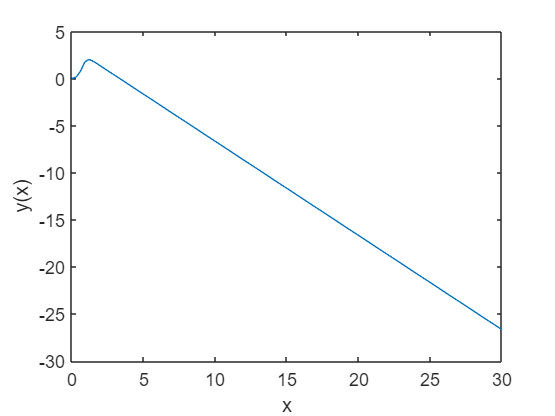


figure(1)
plot(x,y)
xlabel("x")
ylabel("y(x)")